# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to Sunday 19th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix 

Eaa2rotMat([1;0;0],2*pi)

ans =     1.0000         0         0
         0    1.0000    0.0000
         0   -0.0000    1.0000


det(ans)

ans = 1

- Compare the transpose and the inverse of the resulting matrix

ans'

ans = 1

inv(ans)

ans = 1

%Tant la inversa com la transposada són 1

- Using the output matrix, transform a vector parallel to the axis of rotation. 

r_mat=Eaa2rotMat([0;0;1],pi/4)

r_mat =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


vec=[0;0;5]

vec =      0
     0
     5


r_mat*vec

ans =      0
     0
     5


What happens?

    El vector queda igual que al principi. Això es degut a que al ser un vector paralel a l'eix de rotació, la seva transformació   serà igual que l'eix.

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the escalar product between the original  vector and the transformed one.

r_mat

r_mat =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


vec1=[0;1;0]

vec1 =      0
     1
     0


r_mat*vec1

ans =    -0.7071
    0.7071
         0


dot(vec1,ans)

ans = 0.7071

 What you observe?

    El producte escalar es igual al cosinus de l'angle al que rotem l'eix.

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5)

axisM =     0.0038   -0.1469   -0.4577    0.1671   -0.1390   -0.4807    0.1513   -0.3780   -0.1683   -0.3783    0.4300   -0.1576    0.0449   -0.4452   -0.3045    0.3778    0.4227    0.0437    0.3390    0.0607    0.0039   -0.3613    0.2881   -0.3665   -0.1992   -0.2134    0.0975    0.0492   -0.4741    0.0212    0.3295    0.0932    0.1685   -0.4279    0.4337    0.2567    0.4880   -0.0453    0.3828    0.0989   -0.0496    0.2626    0.1732   -0.0927   -0.2166   -0.1100    0.3344   -0.1740    0.3844    0.1748
   -0.0104   -0.0506    0.4730    0.0864    0.1203   -0.4161   -0.2688   -0.2316   -0.3478    0.3842   -0.1010    0.2360    0.1862   -0.1963    0.2202    0.0824    0.3004    0.4848   -0.0667   -0.2309    0.1468   -0.0244    0.2803   -0.4784    0.4394    0.3008    0.3840    0.2284   -0.0535   -0.1277    0.3491    0.3726   -0.2932   -0.0933    0.3110   -0.0830    0.3641   -0.2533    0.4137   -0.3511   -0.2943    0.3825    0.1643   -0.2247    0.3962   -0.0021    0.1096   -0.0436    0.2209 

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100)

theta =          0    0.1904    0.3808    0.5712    0.7616    0.9520    1.1424    1.3328    1.5232    1.7136    1.9040    2.0944    2.2848    2.4752    2.6656    2.8560    3.0464    3.2368    3.4272    3.6176    3.8080    3.9984    4.1888    4.3792    4.5696    4.7600    4.9504    5.1408    5.3312    5.5216    5.7120    5.9024    6.0928    6.2832    6.4736    6.6640    6.8544    7.0448    7.2352    7.4256    7.6160    7.8064    7.9968    8.1872    8.3776    8.5680    8.7584    8.9488    9.1392    9.3296


 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

res_vec=zeros(1,100);
for i=1:1:100
    res_vec(i,1)=trace(Eaa2rotMat(axisM(:,i),theta(1,i)));
end

- Make a plot of the vector that you have obtained vs the theta angle. Explain what you observe.

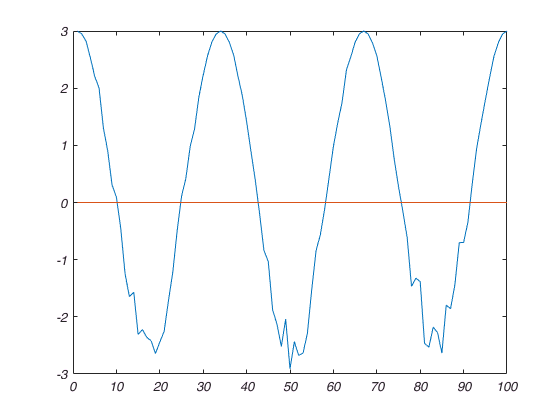

plot(res_vec)

               * La gràfica esbastant similar a el comportament d'un cosinus. Com podem veure a theta, els angles van de 0 a 6*pi donant aixi 3 voltes a la         circunferencia. A la gràfica ho podem veure representat amb tres periodes.*

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

r_mat=Eaa2rotMat([0;0;1],pi/2)

r_mat =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


[res_axis,res_ang]=rotMat2Eaa(r_mat)

res_axis =      0
     0
     1


res_ang = 1.5708

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

     r1=[1 0 0;0 1 0;0 0 1];
    r2=[-1/2 2/3 2/3;2/3 -1/3 2/3;2/3 2/3 -1/3];
    r3=[0 0 -1;0 -1 0;-1 0 0];
    
    [res_axis,res_ang]=rotMat2Eaa(r1)

res_axis =    NaN
   NaN
   NaN


res_ang = 0

    [res_axis,res_ang]=rotMat2Eaa(r2)

res_axis =      0
     0
     0


res_ang =    3.1416 - 0.4055i


    [res_axis,res_ang]=rotMat2Eaa(r3)

res_axis =      0
     0
     0


res_ang = 3.1416

*Quan proves de treure l'eix t'adones que cap de les matrius dona un eix definit. Les tres son matrius simetriques i per tant la seva trasposta es igual a ella mateixa. Aixo provoca que a rotMat2Eaa al restar m-m' la matriu resultant sigui 0 i per tant no es pugui operar amb ella.*

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

res_m=r3;
    %res_m=(r-eye(3))*inv(r+eye(3))
x=-res_m(2,3);
y=res_m(1,3);
z=-res_m(1,2);

axis=[x;y;z]

axis =      0
    -1
     0


*Solution here : *

*Segons la formula Cayley podemtrobar l'eix de rotacio d'una matriu simetrica a partir de les anteriors directrius.*

## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( 0, 1, 0)$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ (0.5774 ,0.5774 ,0.5774 )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ (0 ,0 ,0 )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8


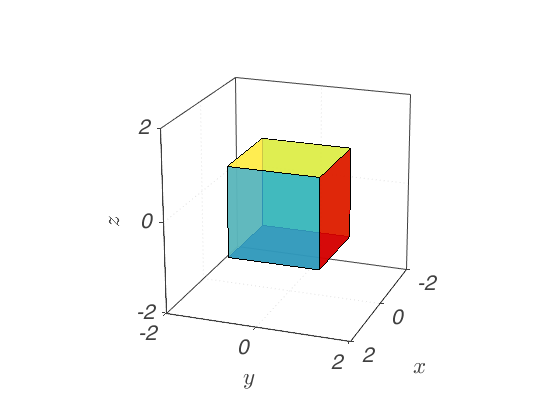

R = eye(3);
M_mod = (R*M')';
Cubeplot(M_mod);

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

test_matrix=eAngles2rotM(pi/2,pi/4,pi/2)

r_euler_matrix =     0.0000   -0.0000    1.0000
    0.7071    0.7071   -0.0000
   -0.7071    0.7071    0.0000


test_matrix =     0.0000   -0.0000    1.0000
    0.7071    0.7071   -0.0000
   -0.7071    0.7071    0.0000


- Calculate the determinant of the resulting rotation matrix 

det(test_matrix)

ans = 1

- Compare the transpose and the inverse of the resulting matrix

test_matrix'

ans =     0.0000    0.7071   -0.7071
   -0.0000    0.7071    0.7071
    1.0000   -0.0000    0.0000


inv(test_matrix)

ans =     0.0000    0.7071   -0.7071
   -0.0000    0.7071    0.7071
    1.0000   -0.0000    0.0000


%tant la trasposta com la inversa són iguals

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

[phi,theta,psi]=rotM2eAngles(test_matrix)

phi = 1.5708

theta = 0.7854

psi = 1.5708

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented

test_matrix=[0 0.3420 0.9397;0 0.9397 -0.3420;-1 0 0]

test_matrix =          0    0.3420    0.9397
         0    0.9397   -0.3420
   -1.0000         0         0


[phi,theta,psi]=rotM2eAngles(test_matrix)

phi = 0

theta = -1

psi = -0.3490

%suposem que un dels angles és 0 ja que si no no es pot resoldre (el resultat real és que phi + psi són iguals a psi)

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.

test_matrix=eAngles2rotM(pi/2,pi/4,pi/2)

r_euler_matrix =     0.0000   -0.0000    1.0000
    0.7071    0.7071   -0.0000
   -0.7071    0.7071    0.0000


test_matrix =     0.0000   -0.0000    1.0000
    0.7071    0.7071   -0.0000
   -0.7071    0.7071    0.0000


[phi,theta,psi]=rotM2eAngles(test_matrix)

phi = 1.5708

theta = 0.7854

psi = 1.5708